# Model Advisor

Copyright 2023-2024 The MathWorks, Inc.

The Model Advisor can check your model or subsystems for configurations or modeling features in order to make sure the model meets certain modeling standards or to avoid inaccurate or inefficient simulations.

% Download example and copy it to a new folder
% Choose destination folder 
destFolder = uigetdir;

% Open example to downloas all related example files
openExample('simulink_automotive/ModelingAnAutomaticTransmissionControllerExample') 

Operation terminated by user during SLStudio.Utils.openModelWithProjectCheck


In openmdl (line 17)
    evalin('base', cmd);
    ^^^^^^^^^^^^^^^^^^^
In openslx (line 9)
out = openmdl(filename);
      ^^^^^^^^^^^^^^^^^
In open (


% Close Simulink model and copy all files to destination folder
close_system('sldemo_autotrans.slx')
currFolder = pwd;
copyfile(currFolder, destFolder)

% Change to destination folder and 
cd(destFolder)
open_system('sldemo_autotrans.slx')

Open the Model Advisor:

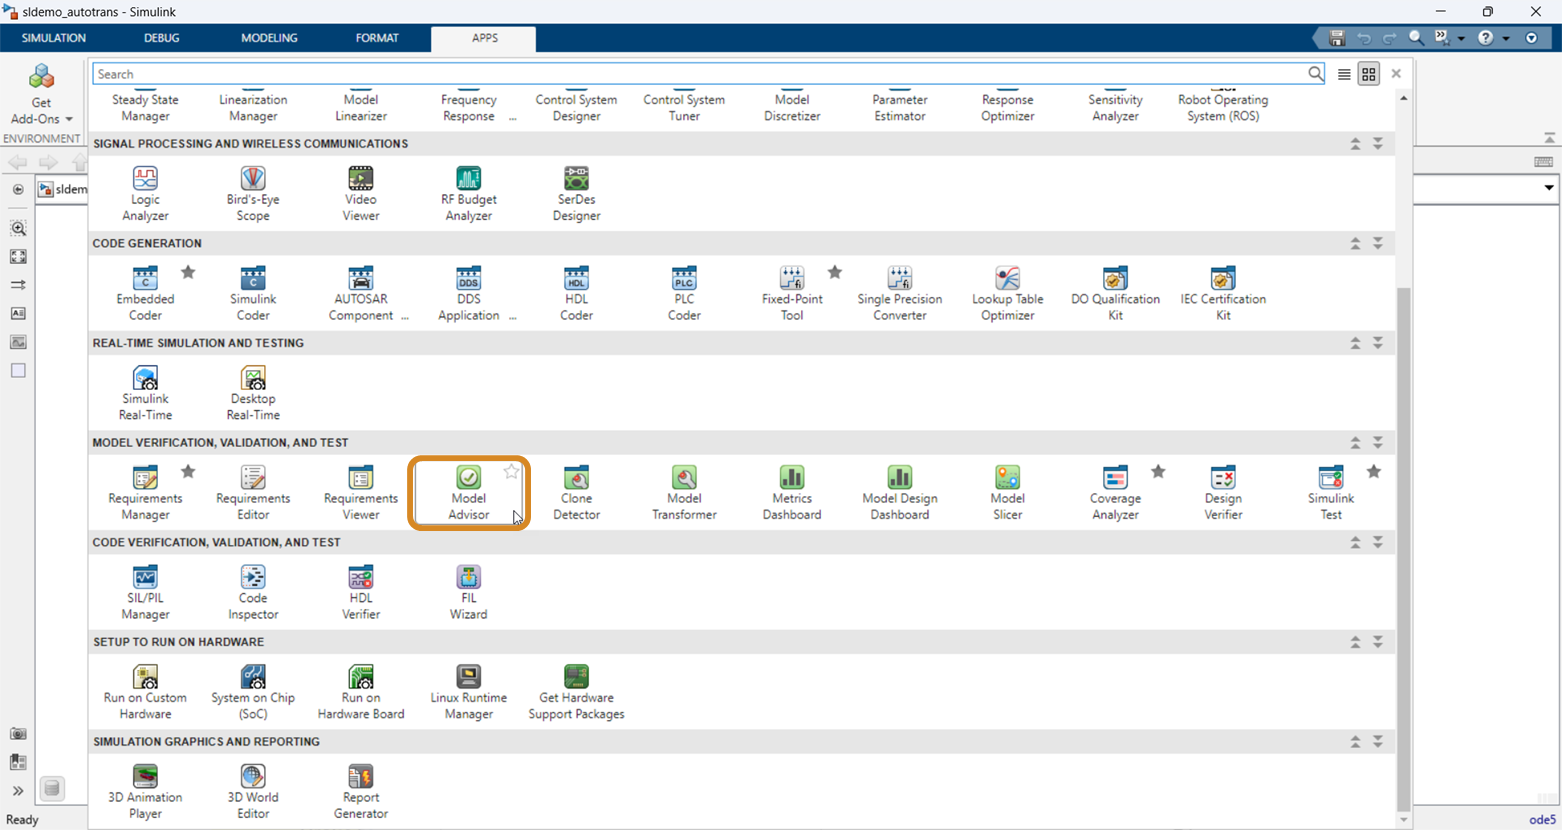

Select components to check:

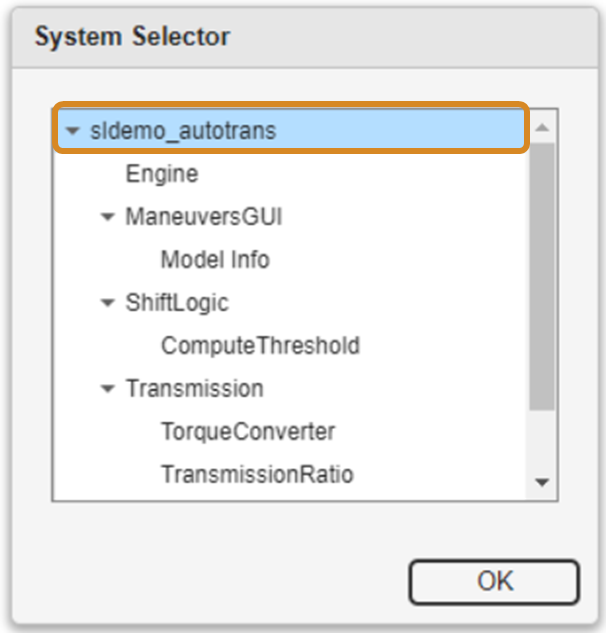

The Model Advisor contains built-in checks and displays all cheks for installed products. They are ordered by product or specifics tasks you might be working on, for example:

- Performance

- Accuracy

- Predictability

- Consistency

- Adherence to standards

Learn more about the checks in different products in [Check Your Model Using the Model Advisor](https://www.mathworks.com/help/releases/R2023a/simulink/ug/select-and-run-model-advisor-checks.html). 

Select a set of available checks and run them ([Modeling Standards for MAB](https://www.mathworks.com/help/releases/R2023a/simulink/mab-modeling-guidelines.html?s_tid=doc_srchtitle) in this example):

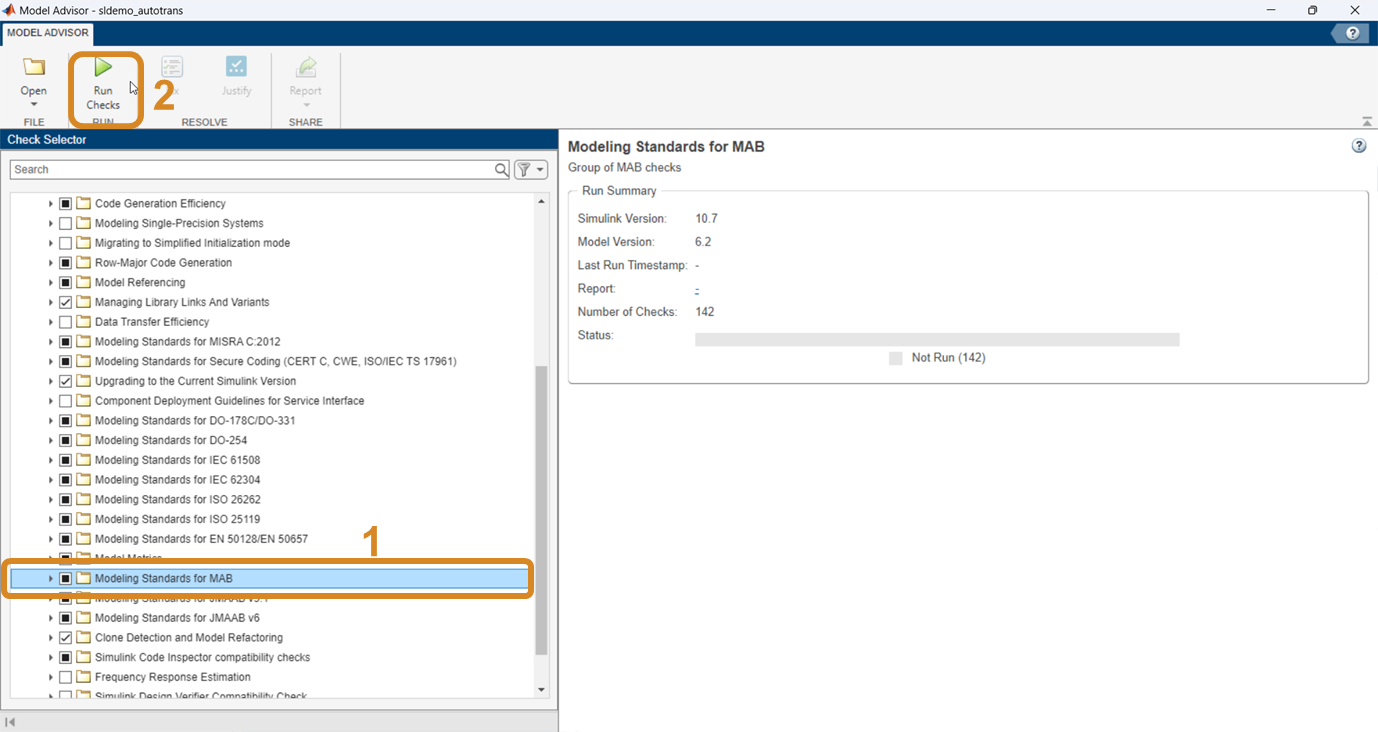

After having run the checks icons will appear next to the individual checks indicating the checks status: *Not Run, Passed, Justified, Warning, Failed, *or* Incomplete*. Selecting one of the run checks provides more details in the right window pane:

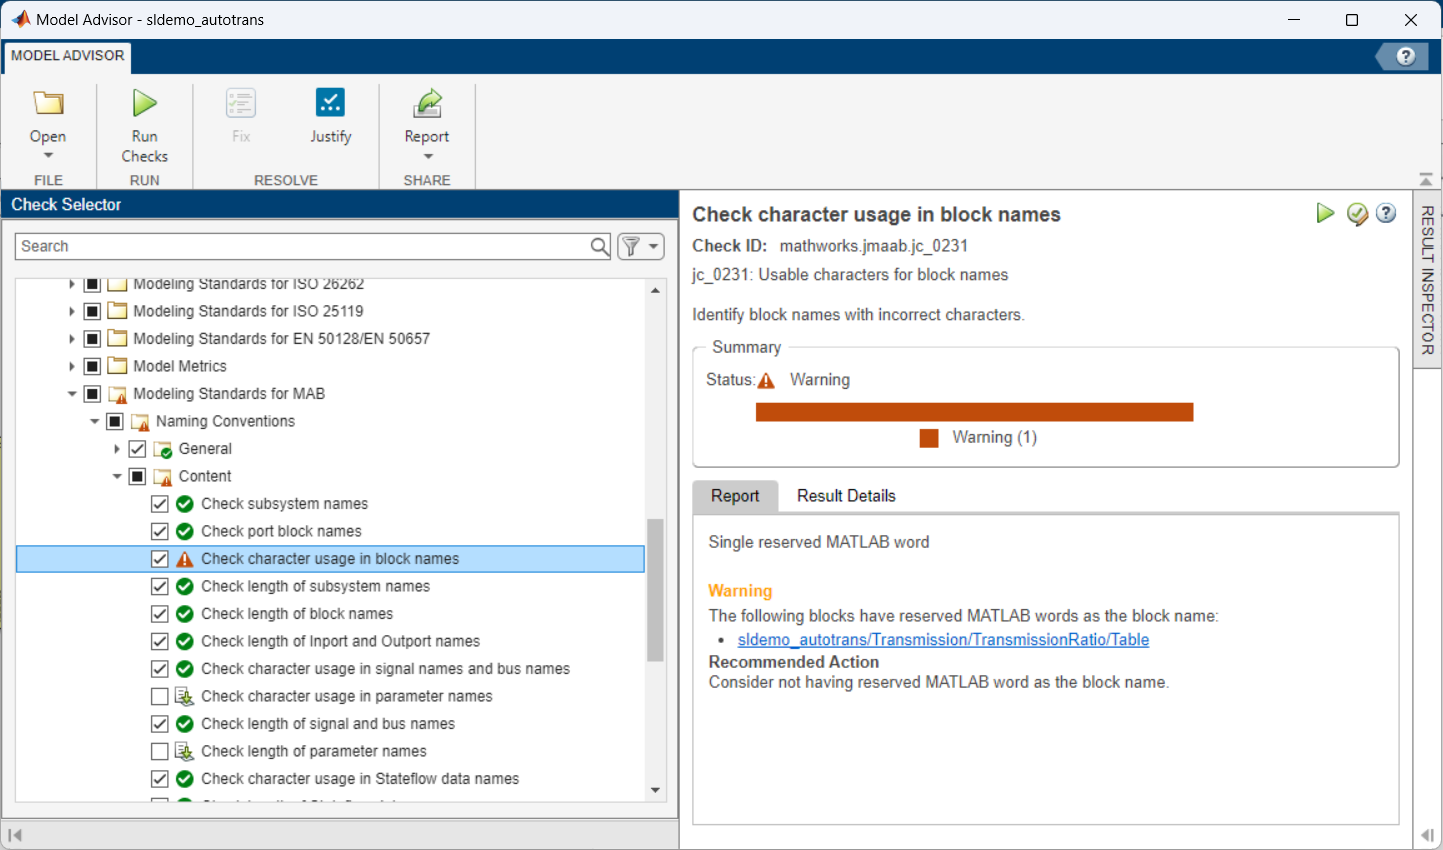

The reports gives details of the selected check as well as recommended actions. This allows to walk through the different checks, review the results, decide if a fix is necessary and depending on that take the recommended action to fix the model. 

# Performance Advisor

The Performance Advisor is built within the Model Advisor framework. It contains a pre-defined set of checks looking for configurations that might cause a simulation slowdown. It also produces a detailed report of the results that suggest improvements that you can manually or automatically apply. 

% Download example and copy it to a new folder
% Choose destination folder 
destFolder = uigetdir;

% Open example to downloas all related example files
openExample('simulink_automotive/ModelingAFaultTolerantFuelControlSystemExample') 

% Close Simulink model and copy all files to destination folder
close_system('sldemo_fuelsys.slx')
currFolder = pwd;
copyfile(currFolder, destFolder)

Error using copyfile
Argument must be a text scalar.


% Change to destination folder and 
cd(destFolder)
open_system('sldemo_fuelsys.slx')

The Performance Advisor will create a baseline simulation before running checks. You can then either have the suggestions applied automatically or manually. In the final step the Performance Advisor runs a validation of the model to see how the performance has improved. So, to be able to use the Performance Advisor: 

- The model should be able to simulate without an error. 

- Data logging should be enabled and at least one signal should be logged

Open the Performance Advisor:

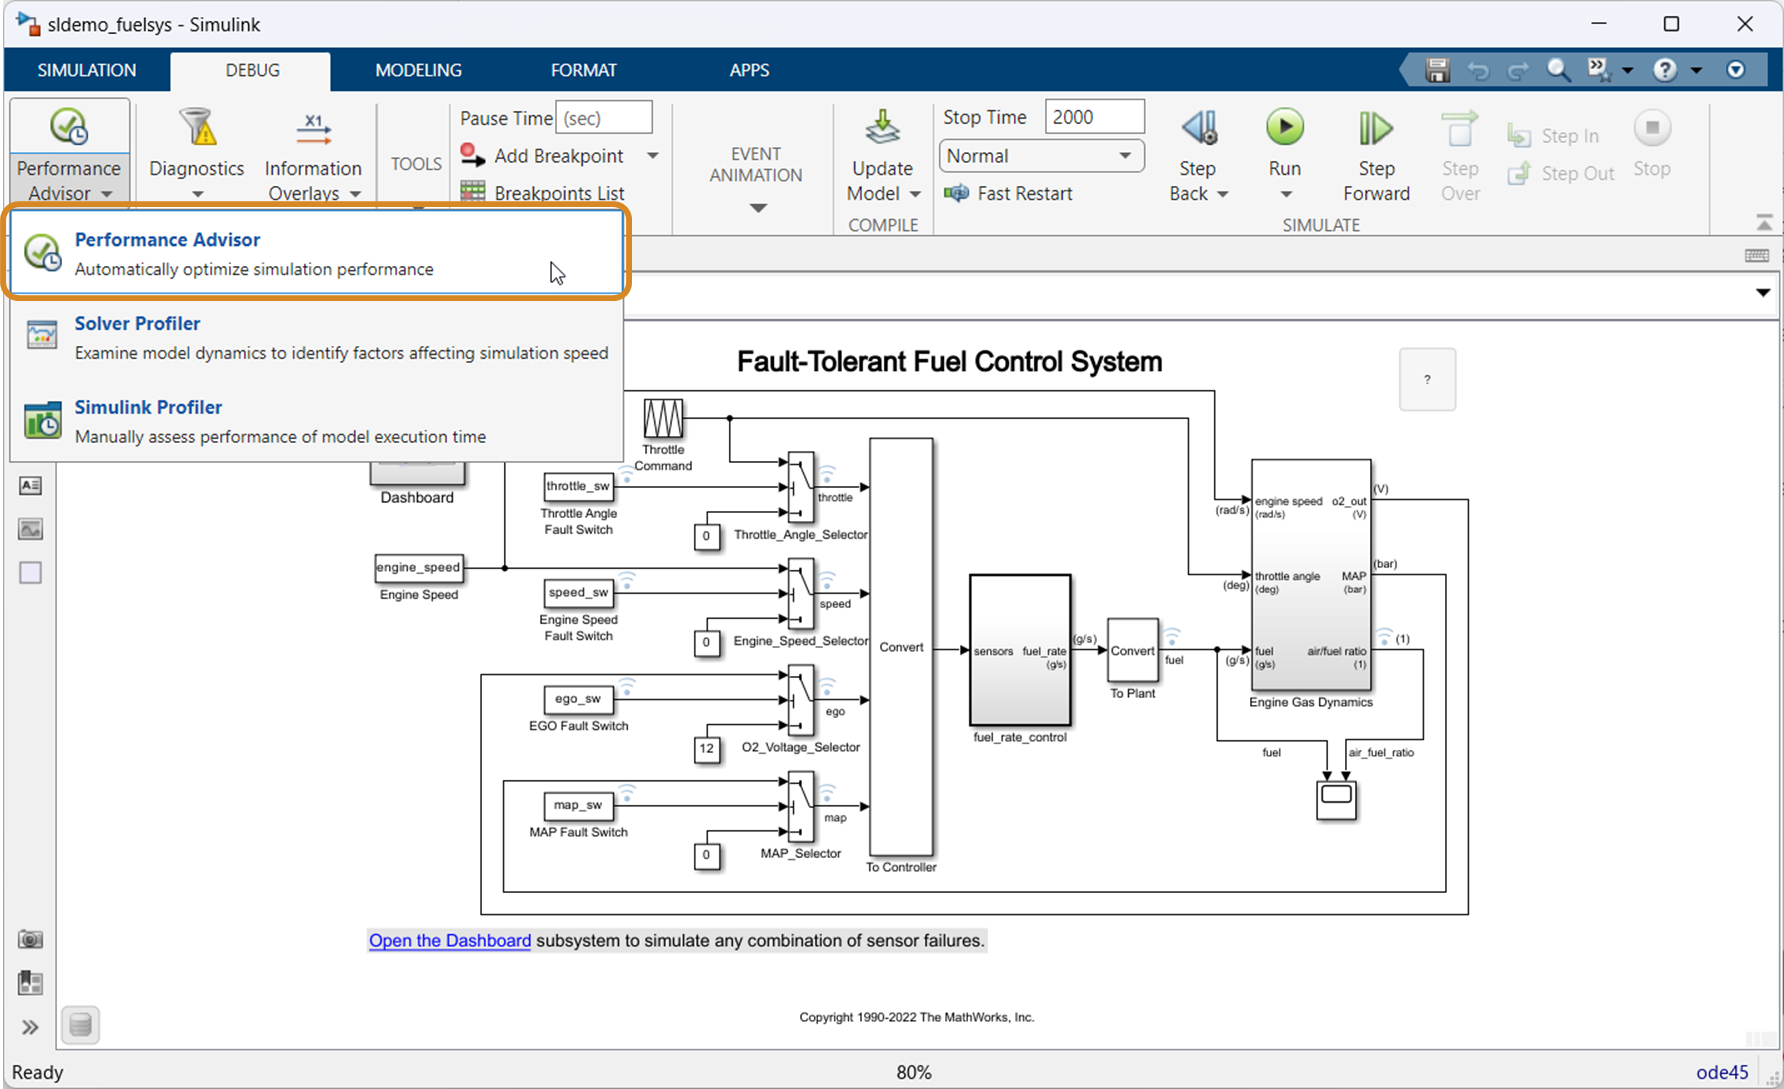

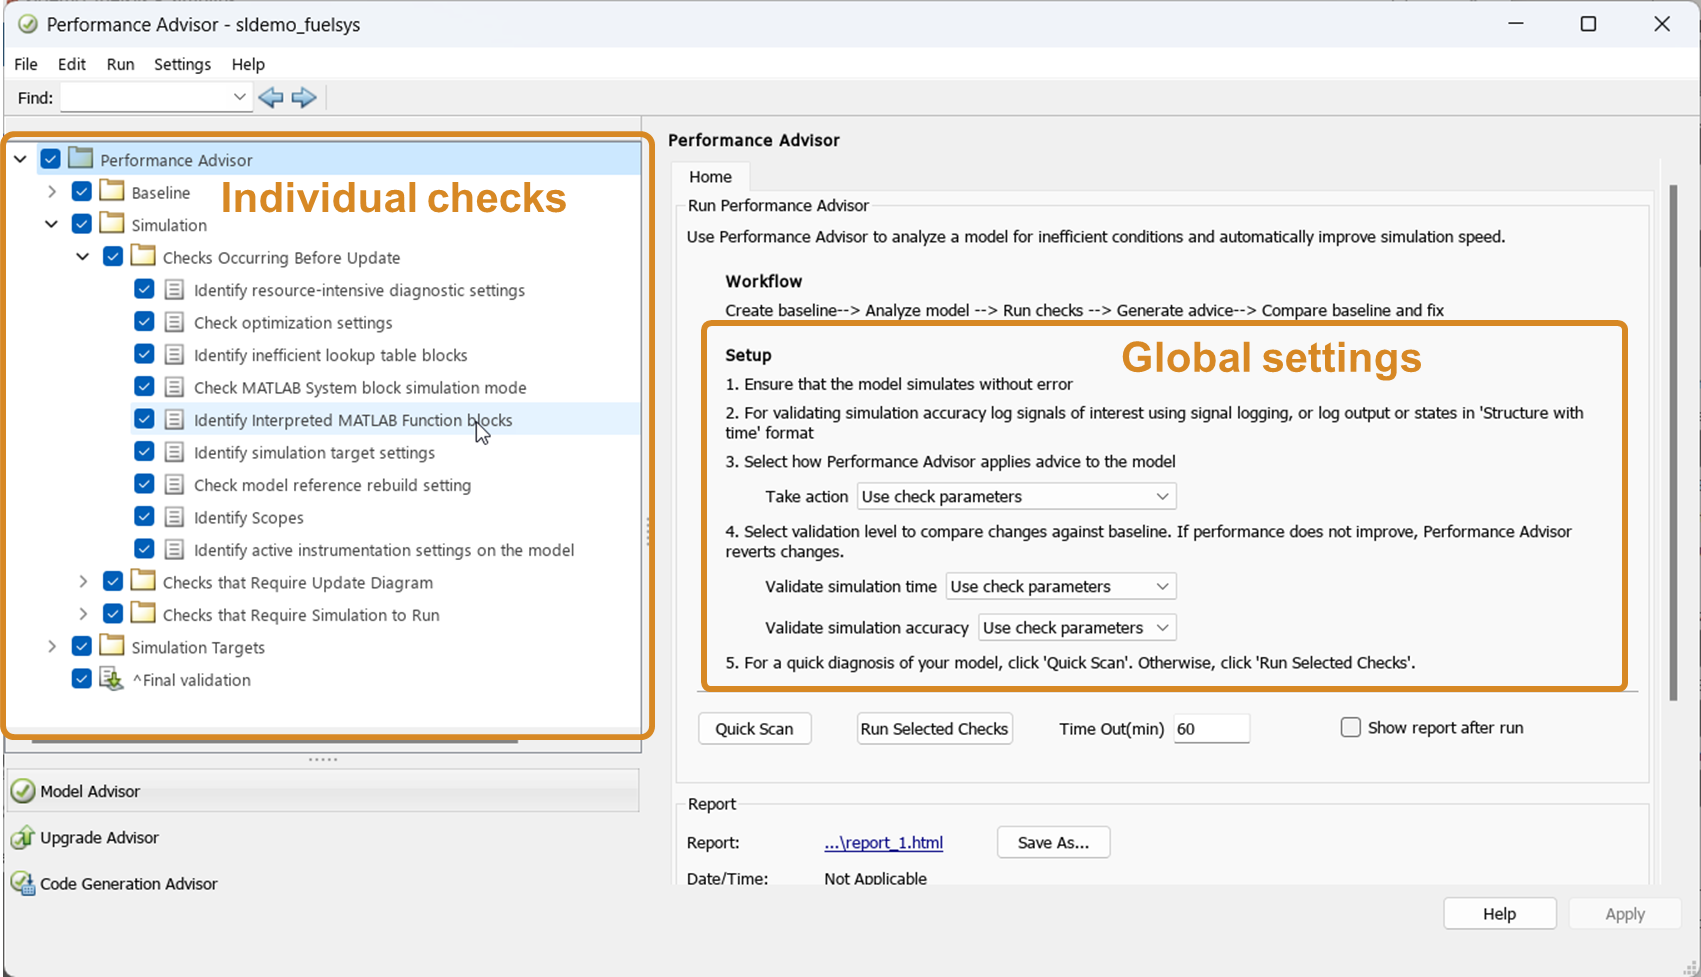

In the left pane you can expand folders to display the checks related to that task. You can select and delect specific checks here. Additionally, you can specifiy input parameters for selected checks. You can either apply global settings for all checks regarding: Taking action on recommendations, validation of simulations time and validation of simulation accuracy. Alternatively you can define these settings for individual checks. Read more in [Run Performance Advisor Checks](https://www.mathworks.com/help/releases/R2023a/simulink/ug/consult-the-performance-advisor.html#buf1sja-1).  

Run the checks (in the following with default settings):

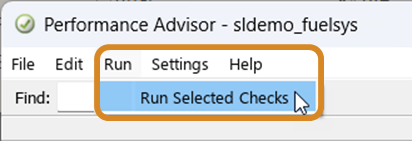

Results report:

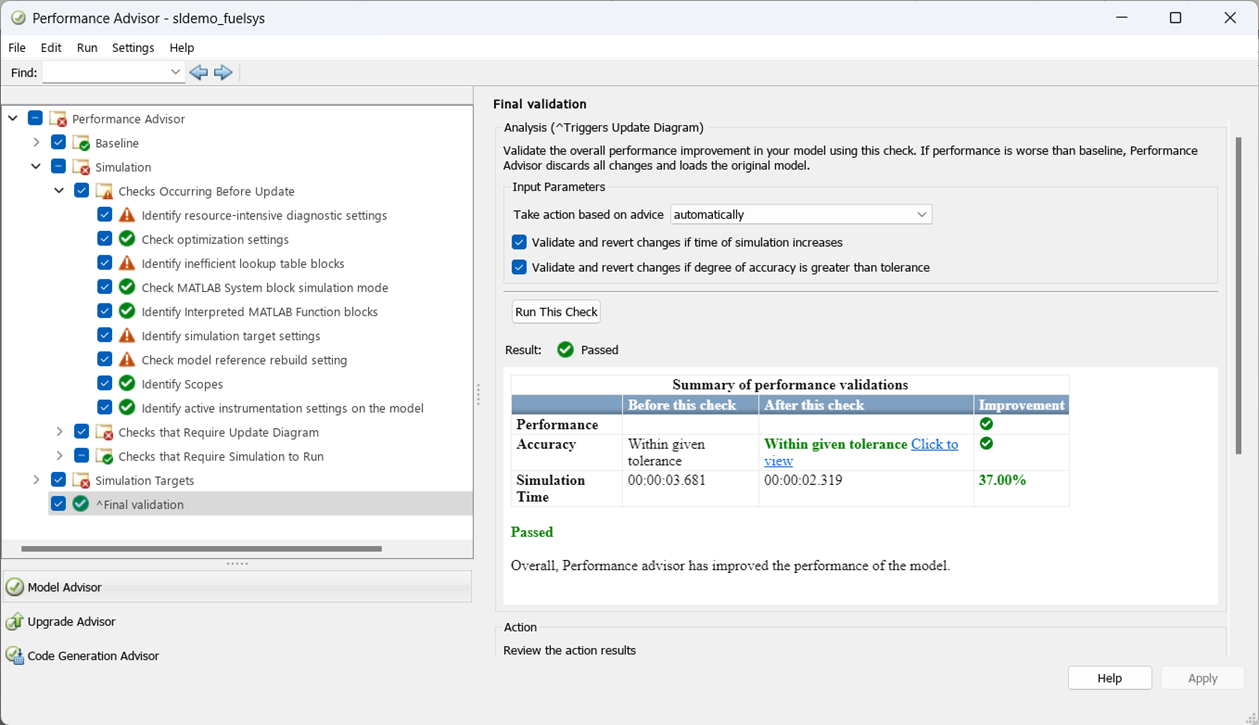

For every check you select on the left pane the right pane will show results:

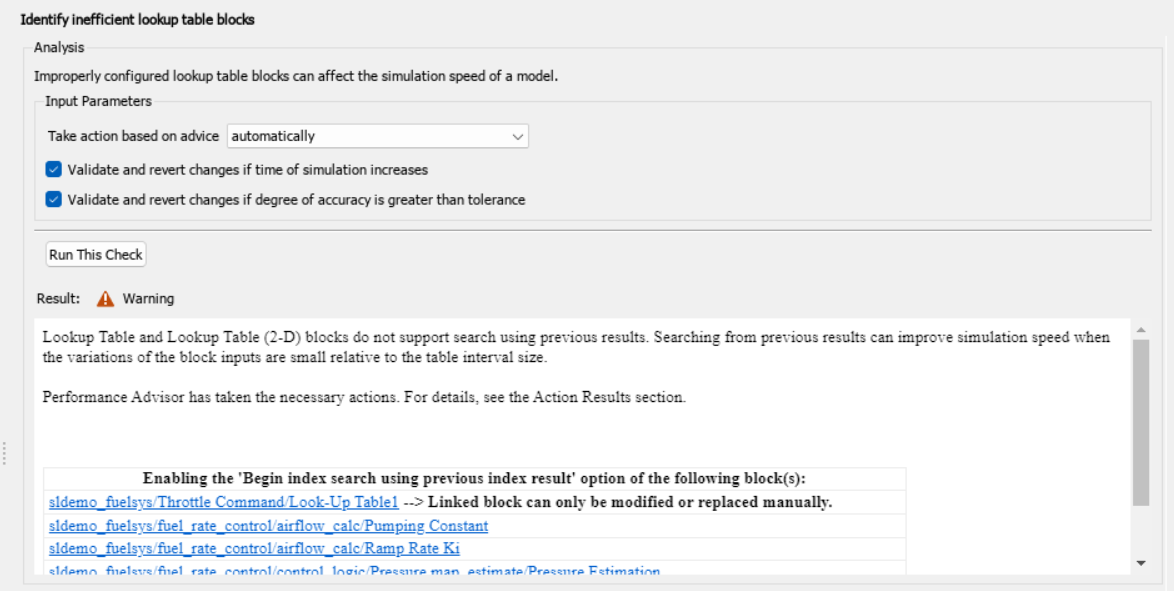

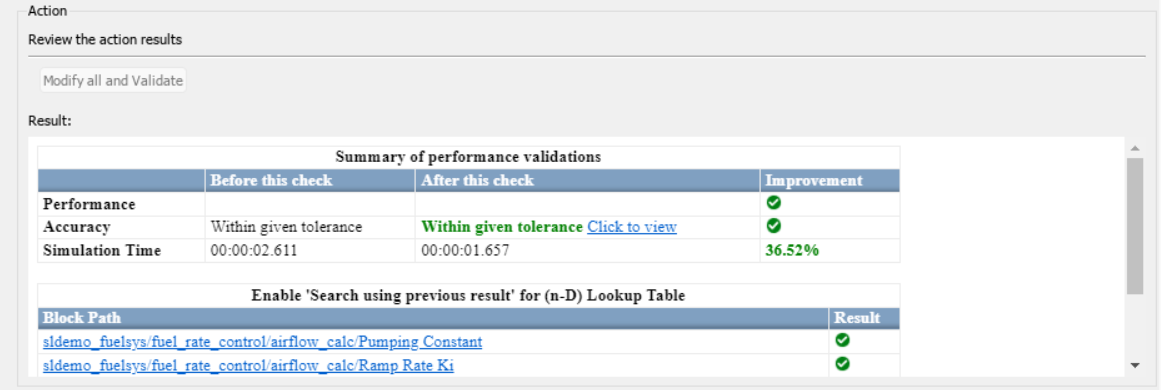

This is divided into two parts. The *Analysis* section contains information about the check, settings to take actions, results of the check. And the *Action* section contains a setting to manually accept all recommendations for the check and a summary of actions taken. 

Based on the results you can use the *Take action based on advice* parameter (*Analysis* section) to select of you want to manually or automatically take action. If recommendations are already applied based on the global setting, some options might be grayed out. 

**Note: **Before running the Performance Advisor, you can choose to use the [*Quick Scan*](https://www.mathworks.com/help/releases/R2023a/simulink/ug/preliminary-setup.html) diagnosis. This is a faster method to diagnose settings and create an initial performance anaylsis, this option won't comipler or change the model or validate any fixes. 

% ToDo: Note regarding use on Simscape?